# Oskar Chrostowski

# Lista 4

### Przydatne polecenia:

`xlabel('text')` - etykieta osi $x$.

`ylabel('text')` - etykieta osi $y$.

`title('text')` - tytuł wykresu.

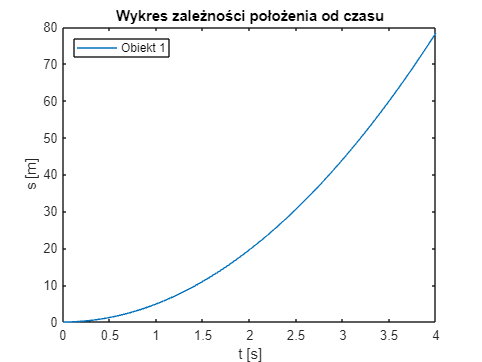

t = linspace(0,4,100);
plot(t, 1/2*9.8*t.^2)
xlabel('t [s]')
ylabel('s [m]')
title('Wykres zależności położenia od czasu')
legend('Obiekt 1','location', 'northwest')

**Zad. 1.** Suma ciągów geometrycznych $$1 + r + r^2 + r^3 + \ldots + r^n$$ zbliża się do granicy $ $\frac{1}{1-r}$$ dla $$r<0$$, gdy $$n\rightarrow \infty$$. Utwórz wektor $$n$$ składający się z 11 elementów od 0 do 10. Przyjmij $$r = 0.5$$ i utwórz kolejny wektor $$x = [r^0\: r^1\: r^2 \ldots r^n]$$ za pomocą polecenia `x=r.^n`. Następnie oblicz sumę elementów tego wektora stosując polecenie `s=sum(x)`. Oblicz granicę $$\frac{1}{1-r}$$ i porównaj z obliczoną sumą $$s$$. Powtórz tę procedurę przyjmując $$n$$ od 0 do 50, a następnie od 0 do 100.

%N od 0 do 10
n=0:10;
r=0.5;
x=r.^n;
s=sum(x)

s = 1.9990

granica = 1./(1-x)

granica =        Inf    2.0000    1.3333    1.1429    1.0667    1.0323    1.0159    1.0079    1.0039    1.0020    1.0010


%N od 0 do 50
n1=0:50;
x1=r.^n1;
s1=sum(x1)

s1 = 2.0000

granica1=1./(1-x1)

granica1 =        Inf    2.0000    1.3333    1.1429    1.0667    1.0323    1.0159    1.0079    1.0039    1.0020    1.0010    1.0005    1.0002    1.0001    1.0001    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



%N od 0 do 100
n2=0:100;
x2=r.^n2;
s2=sum(x2)

s2 = 2

granica2=1./(1-x2)

granica2 =        Inf    2.0000    1.3333    1.1429    1.0667    1.0323    1.0159    1.0079    1.0039    1.0020    1.0010    1.0005    1.0002    1.0001    1.0001    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


**Zad. 2**. Sporządź wykresy $$y = \sin x$$ oraz $$y = \cos x$$ dla $$0\leq x \leq 2\pi$$ opierając go na 100 punktach rozmieszczonych liniowo w określonych odstępach. Opisz osie i zatytułuj ,,Wykres sporządzony przez \textit{imię nazwisko}''. Na drugim podwykresie narysuj te same krzywe zaznaczając punkty kółkami bez ich łączenia (`plot(x,y,'o')`)`.`

clf()
x=linspace(0,2.*pi,100);
y1=sin(x)

y1 =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317


y2=cos(x)

y2 =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995


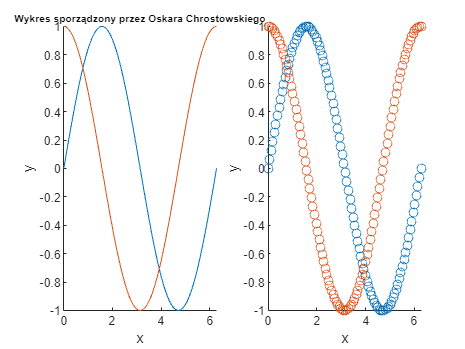

subplot(1,2,1)
hold on
plot(x,y1)
plot(x,y2)
xlabel('x')
ylabel('y')
title('Wykres sporządzony przez Oskara Chrostowskiego','FontSize',7)
hold off

subplot(1,2,2)
hold on
plot(x,y1,'o')
plot(x,y2,'o')
xlabel('x')
ylabel('y')
hold off

**Zad. 3.** Za pomocą polecenia `p``lot3(x,y,z)` wykreśl okrągłą sprężynę$ $x(t) = \sin(t)$, $y(t) = \cos(t)$, $z(t) = t$$, dla $$0 \leq t \leq 20$$. Opisz osie i zatytułuj wykres.

clf()
t=linspace(0,20,100)

t =          0    0.2020    0.4040    0.6061    0.8081    1.0101    1.2121    1.4141    1.6162    1.8182    2.0202    2.2222    2.4242    2.6263    2.8283    3.0303    3.2323    3.4343    3.6364    3.8384    4.0404    4.2424    4.4444    4.6465    4.8485    5.0505    5.2525    5.4545    5.6566    5.8586    6.0606    6.2626    6.4646    6.6667    6.8687    7.0707    7.2727    7.4747    7.6768    7.8788    8.0808    8.2828    8.4848    8.6869    8.8889    9.0909    9.2929    9.4949    9.6970    9.8990


x3=sin(t)

x3 =          0    0.2006    0.3931    0.5696    0.7230    0.8469    0.9364    0.9878    0.9990    0.9696    0.9007    0.7952    0.6574    0.4928    0.3082    0.1111   -0.0906   -0.2886   -0.4748   -0.6418   -0.7826   -0.8916   -0.9643   -0.9978   -0.9908   -0.9434   -0.8576   -0.7370   -0.5864   -0.4120   -0.2207   -0.0206    0.1805    0.3742    0.5526    0.7086    0.8358    0.9289    0.9843    0.9997    0.9744    0.9094    0.8075    0.6727    0.5106    0.3277    0.1315   -0.0701   -0.2688   -0.4566


y3=cos(t)

y3 =     1.0000    0.9797    0.9195    0.8219    0.6909    0.5318    0.3510    0.1560   -0.0453   -0.2449   -0.4344   -0.6063   -0.7536   -0.8701   -0.9513   -0.9938   -0.9959   -0.9575   -0.8801   -0.7669   -0.6225   -0.4529   -0.2647   -0.0659    0.1357    0.3317    0.5143    0.6759    0.8100    0.9112    0.9753    0.9998    0.9836    0.9274    0.8334    0.7056    0.5491    0.3702    0.1763   -0.0248   -0.2249   -0.4158   -0.5898   -0.7399   -0.8598   -0.9448   -0.9913   -0.9975   -0.9632   -0.8897


z=t

z =          0    0.2020    0.4040    0.6061    0.8081    1.0101    1.2121    1.4141    1.6162    1.8182    2.0202    2.2222    2.4242    2.6263    2.8283    3.0303    3.2323    3.4343    3.6364    3.8384    4.0404    4.2424    4.4444    4.6465    4.8485    5.0505    5.2525    5.4545    5.6566    5.8586    6.0606    6.2626    6.4646    6.6667    6.8687    7.0707    7.2727    7.4747    7.6768    7.8788    8.0808    8.2828    8.4848    8.6869    8.8889    9.0909    9.2929    9.4949    9.6970    9.8990


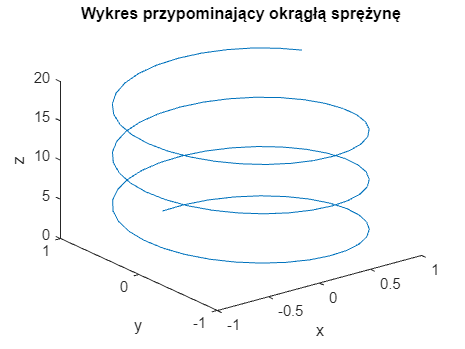


plot3(x3,y3,z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Wykres przypominający okrągłą sprężynę')